# EJERCICIOS TEMA 5 

## E1A 

### Respuesta: 

####     GaussJordan

**a) **

Ajustamos los puntos de la forma $y\;=a_1 \frac{\;\;1}{x}+a_2 \;x\;$ donde: 


$$y=\frac{P^2 }{4\;\pi^2 }\;,a_{1\;} =\frac{R^2 }{g}\;,a_{2\;} =\frac{1}{g}$$


clc, clear, clf 

% Datos
x = 5: 5 : 45; 
x = x / 100; % cm a m 

P = [2.62 1.936 1.668 1.568 1.520 1.512 1.536 1.576 1.6];


$$y=\frac{P^2 }{4\;\pi^2 }$$


y = P.^2 / ( 4.* pi.^2);

% Solución 
Z = [ 1./x' x'];
A = Z' * Z; 
b = Z' * y';
sol = GaussJordan(A,b);

fprintf('La función de ajuste es y = %.4f·1/x + %.4f·x', sol(1), sol(2))

La función de ajuste es y = 0.0084·1/x + 0.1020·x

**b) **Cálculo de radio de giro y g


$$a_{2\;} =\frac{1}{g}\;\to g=\frac{1}{a_{2\;} }\;\;$$
 


$$a_{1\;} =\frac{R^2 }{g}\;\to R=\sqrt{g\cdot a_{1\;} \;}\;$$


g = 1 / sol(2);
R = sqrt( g * sol(1));

fprintf('El valor estimado de la gravedad es %6.4f(m/s^2)\n',g)

El valor estimado de la gravedad es 9.8081(m/s^2)


fprintf('El valor del radio de giro es %6.4f m\n',R)

El valor del radio de giro es 0.2875 m


**c) **

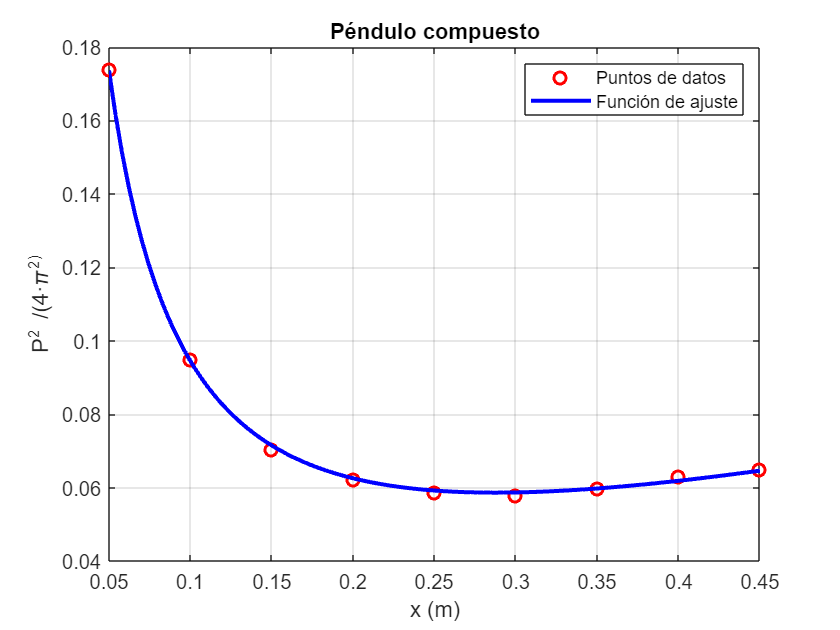

plot(x,y,'or','LineWidth',1.5)
hold on

% Dibujo de la función de ajuste y= a/x +bx
xp = linspace(5,45,100);
xp = xp/100;

yp = sol(1)./xp + sol(2).*xp;
plot(xp,yp,'b','LineWidth',2)

title('Péndulo compuesto')
xlabel('x (m)')
ylabel('P^2 /(4·\pi^2)')
grid on 
legend('Puntos de datos','Función de ajuste')
hold off

**d) **

% Error 
er = sum((y' - Z*sol).^2);
fprintf('El error del ajuste es %6.4e\n',er)

El error del ajuste es 3.5770e-06



% Desviación Estándar
s = sqrt(er/(length(x)-length(sol)));
fprintf('La desviación estándar del ajuste es: %6.4e\n',s)

La desviación estándar del ajuste es: 7.1484e-04


## E2A

### Respuesta: 

####     GaussJordan

**a)**


$$p\left(t\right)=A\;e^{-1\ldotp 5t} +{\mathrm{Be}}^{-0\ldotp 3t} +{\mathrm{Ce}}^{-0\ldotp 05t}$$


Empleamos mínimos cuadrados generales

clc, clear, clf 

% Datos
t = [0.5 1 2 3 4 5 6 7 9]';
p = [6 4.4 3.2 2.7 2 1.9 1.7 1.4 1.1]';
Z = [exp(-1.5.*t) exp(-0.3.*t) exp(-0.05.*t)];

% Solución

A = Z' * Z;
b = Z' * p;

sol = GaussJordan(A,b);

fprintf('La ecuación de la función de ajuste es %.4f · e^(-1.5t) + %.4f · e^(-0.3t) + %.4f · e^(-0.05t)', sol(1), sol(2), sol(3))

La ecuación de la función de ajuste es 4.1375 · e^(-1.5t) + 2.8959 · e^(-0.3t) + 1.5349 · e^(-0.05t)

fprintf('A = %6.4f ppm\nB = %6.4f ppm\nC = %6.4f ppm\n',sol(1), sol(2), sol(3))

A = 4.1375 ppm
B = 2.8959 ppm
C = 1.5349 ppm


**b)**

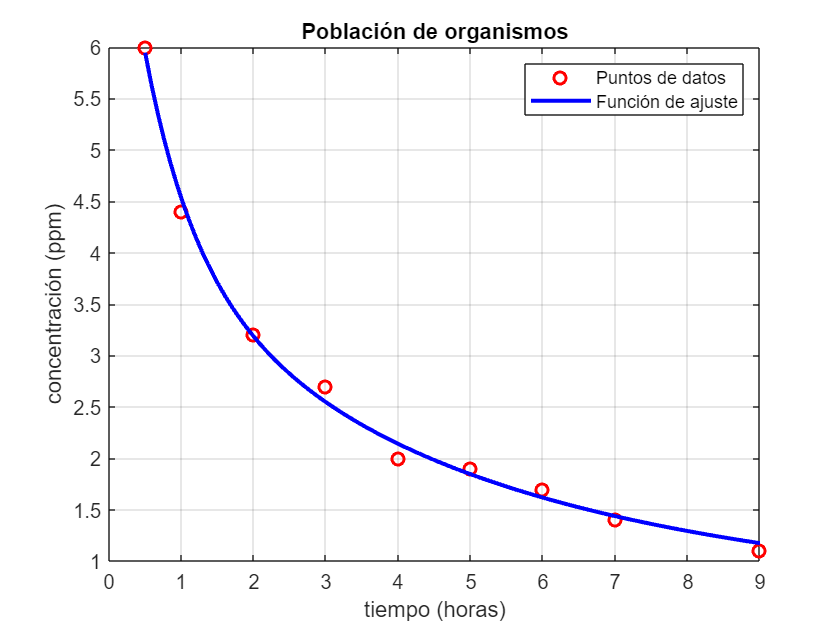

f = @(x) sol(1) .* exp(-1.5 .* x) + sol(2) .* exp(-0.3 .* x) + sol(3) .* exp(-0.05 .* x);

x = linspace(min(t), max(t), 100);
y = f(x);

% Gráfica 
plot(t,p,'or','LineWidth',1.5)
hold on
plot(x,y,'b','LineWidth',2)
grid on 

xlabel('tiempo (horas)')
ylabel('concentración (ppm)')
legend('Puntos de datos','Función de ajuste')
title('Población de organismos')
hold off

**c) **

Cálculo del error y Desviación estándar

er = sum((p - f(t)).^2);
fprintf('El error del ajuste es: %6.4f\n',er);

El error del ajuste es: 0.0803


s = sqrt(er/(length(t)-length(sol)));
fprintf('La desviación estándar del ajuste es: %6.4f\n',s)

La desviación estándar del ajuste es: 0.1157


**d)**

hora = 3.5;
fprintf('La concetración al cabo de 3.5 horas será de %6.4f ppm\n',f(hora))

La concetración al cabo de 3.5 horas será de 2.3236 ppm


## E1B

### Respuesta: 

####     regresionlineal


$$\sigma_t =\frac{F}{A_0 }\;\frac{L}{L_0 }\;,\epsilon_t =\ln \left(\frac{L}{L_0 }\right)$$


**a) **

Linealizamos la ecuación $\sigma_t =K\cdot \varepsilon_t^m$ tomando logaritmos a ambos lados de la ecuación: 


$$\log \left(\sigma_t \right)=m\;\log \left(\varepsilon_t \right)+\log \left(K\right)$$


Calculamos la recta de ajuste sobre $\log \left(\sigma_t \right)$ y $\log \left(\varepsilon_t \right)$

clc, clear, clf 

% Datos 
F = [24.6 29.3 31.5 33.3 34.8 35.7 36.6 37.5 38.8 39.6 40.4];
F = F*1000; % Paso de kN a N

L = [12.58 12.82 12.91 12.95 13.05 13.21 13.35 13.49 14.08 14.21 14.48];
L = L*1e-3; % paso de mm a m

A0 = 1.25*1e-4; % m^2
L0 = 0.0125; % m

sigma = (F.*L) / (A0*L0);
ep = log(L/L0);

% Ajuste a una curva exponencial 
[a, Er] = RegresionLineal(log(ep),log(sigma));
K = exp(a(2));
m = a(1);

fprintf('Los coeficientes de la función de ajuste son: K = %6.4e y m = %6.4f\n',K,m)

Los coeficientes de la función de ajuste son: K = 5.4948e+08 y m = 0.2085


**b) **

Error de ajuste

fprintf('El error del ajuste es: %6.6f\n',Er)

El error del ajuste es: 0.027013


**c) **

Gráfica 

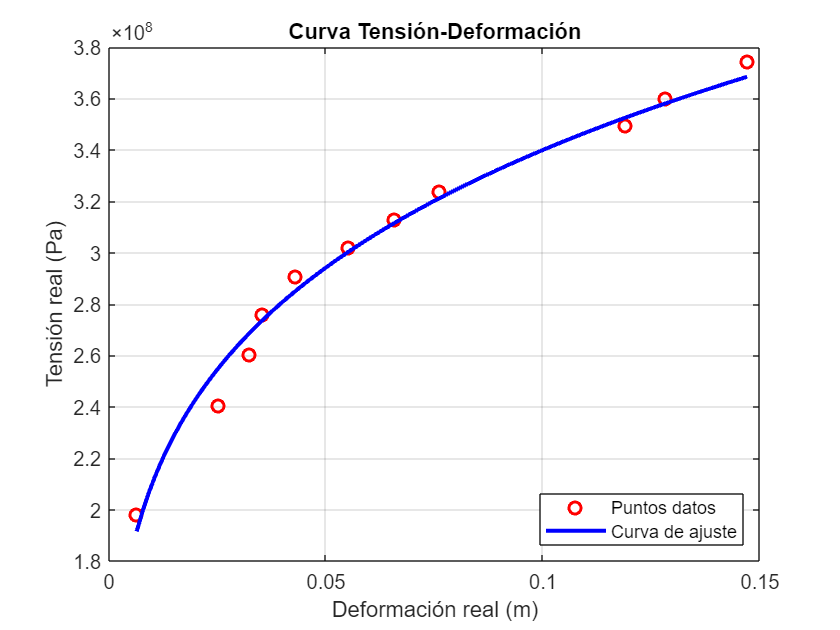

x = linspace(ep(1),ep(end),100);
y = K * x.^m;

plot(ep,sigma,'or','LineWidth',1.5)
hold on
plot(x,y,'b','LineWidth',2)

grid on
legend('Puntos datos','Curva de ajuste','Location','southeast')
xlabel('Deformación real (m)')
ylabel('Tensión real (Pa)')
title('Curva Tensión-Deformación')
hold off

**d) **

Fuerza aplicada en N para una longitud de $L=13\ldotp 55\;\mathrm{mm}$ . 

L13 = 13.55*1e-3;
ep13 = log(L13/L0);
sigma13 = K * ep13.^m; % Tensión real
Fr = sigma13 * A0 * L0 / L13;
fprintf('La fuerza aplicada para L = 13.55 mm es de %.0f N\n',Fr)

La fuerza aplicada para L = 13.55 mm es de 37483 N


## E2B 

### Respuesta: 

**a) **

 Linealizamos la ecuación $\gamma =a\cdot e^{-\mathrm{bt}}$ tomando logaritmos a ambos lados: $\log \left(\gamma \right)=-b\cdot t+\log \left(a\right)$ y calculamos la recta de ajuste sobre $t$ y $\log \left(\gamma \right)$ 

clc, clear, clf

% Datos 
t = 0:0.5:5.5;
gamma = [1 0.994 0.990 0.985 0.979 0.977 0.972 0.969 0.967 0.960 0.956 0.952];

% solución 
[a, Er] = RegresionLineal(t, log(gamma));
b = -a(1);
a = exp(a(2));
fprintf('Los coeficientes de la función de ajuste son a = %.4f y b = %.6f\n',a,b)

Los coeficientes de la función de ajuste son a = 0.9984 y b = 0.008640


**b) **

fprintf('El error del ajuste es: %.8f\n',Er)

El error del ajuste es: 0.00127434


**c) **

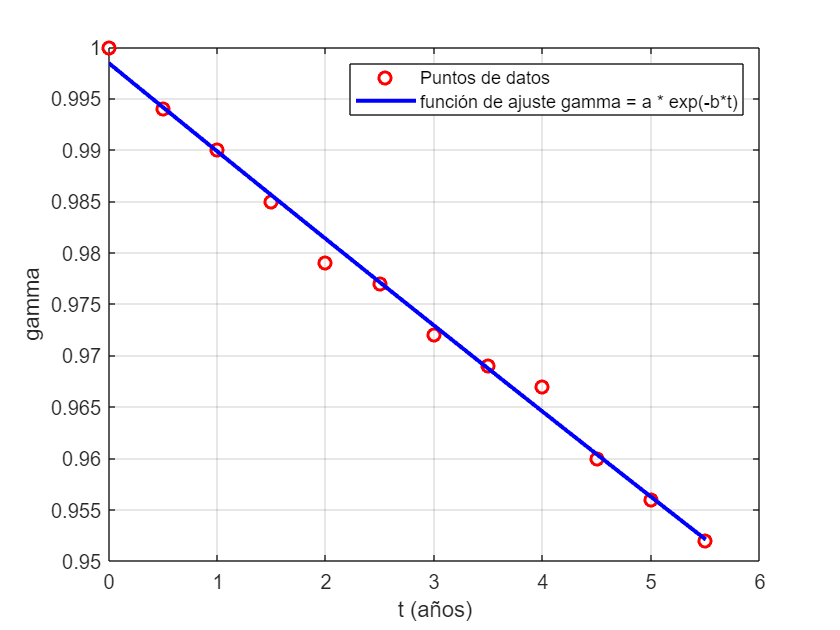

tp = linspace(0,5.5,100);
gp = a .* exp(-b.*tp);

plot(t,gamma,'or','LineWidth',1.5)
hold on
plot(tp,gp,'b','LineWidth',2)
grid on 

xlabel('t (años)')
ylabel('gamma')
legend ('Puntos de datos','función de ajuste gamma = a * exp(-b*t)')
hold off

**d) **

Tomando $\gamma =0\ldotp 5=a\cdot e^{-\mathrm{bt}\;} \to \log \left(0\ldotp 5\right)=\log \left(a\right)-b\cdot t\to t=\frac{\log \left(a\right)-\log \left(0\ldotp 5\right)}{b}$

vm = (log(a) - log(0.5)) / b;
fprintf('La vida media es de %.2f años\n',vm)

La vida media es de 80.05 años
